%% Convex Optimization using Newton's Method
%  Minimizes a convex function f(x) using Newton's method with
%  Backtracking Line Search (Armijo condition).
%
%  Example objective:
%       f(x1, x2) = (x1 - 3)^2 + (x2 - 2)^2 + x1*x2
%
%  Analytic solution (set ∇f = 0):
%       2x1 + x2 = 6
%       x1 + 2x2 = 4   =>  x* = [8/3, 2/3]
%
%  Newton step:  Δx = -H(x)^{-1} ∇f(x)
%  Newton decrement: λ² = ∇f(x)ᵀ H(x)^{-1} ∇f(x)
%  Stop when λ²/2 < tol
%
%  Author : Generated Example
%  Method : Pure Newton with Backtracking Line Search

clear; clc; close all;

%% ── 1. Problem Definition ────────────────────────────────────────────────

% Objective function  f(x)
f = @(x) (x(1) - 3)^2 + (x(2) - 2)^2 + x(1)*x(2);

% Gradient  ∇f(x)
grad_f = @(x) [2*(x(1) - 3) + x(2);
               2*(x(2) - 2) + x(1)];

% Hessian  H(x)  [constant for quadratic, but written generally]
hess_f = @(x) [2, 1;
               1, 2];

%% ── 2. Algorithm Parameters ─────────────────────────────────────────────

x0       = [0; 0];      % Starting point
max_iter = 100;         % Maximum Newton iterations
tol      = 1e-9;        % Convergence on Newton decrement  λ²/2

% Backtracking line-search (Armijo)
alpha0   = 1.0;         % Full Newton step initially
beta     = 0.5;         % Step reduction factor
sigma    = 1e-4;        % Sufficient decrease constant

%% ── 3. Newton's Method Iteration ────────────────────────────────────────

x         = x0;
converged = false;

% Storage
hist_x      = zeros(max_iter+1, 2);
hist_f      = zeros(max_iter+1, 1);
hist_gnorm  = zeros(max_iter+1, 1);
hist_lambda = zeros(max_iter+1, 1);
hist_alpha  = zeros(max_iter,   1);

hist_x(1,:)     = x';
hist_f(1)       = f(x);
hist_gnorm(1)   = norm(grad_f(x));

fprintf('\n=================================================================\n');

fprintf('  Convex Optimization — Newton''s Method\n');

  Convex Optimization — Newton's Method


fprintf('=================================================================\n');

fprintf('  Iter |   f(x)          |  ||grad||      |  λ²/2          | α\n');

  Iter |   f(x)          |  ||grad||      |  λ²/2          | α


fprintf('-----------------------------------------------------------------\n');

-----------------------------------------------------------------



for k = 1:max_iter

    g = grad_f(x);
    H = hess_f(x);
    fval = f(x);

    % ── Check positive definiteness of Hessian ────────────────────────
    [~, pd_flag] = chol(H);
    if pd_flag ~= 0
        error('Hessian is not positive definite at iteration %d. f is not convex here.', k);
    end

    % ── Newton step  Δx = -H^{-1} g ──────────────────────────────────
    dx = -H \ g;                        % Solve H*dx = -g  (more stable than inv)

    % ── Newton decrement  λ² = gᵀ H^{-1} g = -gᵀ dx ─────────────────
    lambda2 = -g' * dx;                 % = g' * H^{-1} * g  (always ≥ 0)
    half_lambda2 = lambda2 / 2;

    hist_lambda(k) = half_lambda2;

    fprintf('  %4d | %15.9f | %14.6e | %14.6e | —\n', ...
            k, fval, norm(g), half_lambda2);

    % ── Convergence check (Newton decrement criterion) ────────────────
    if half_lambda2 < tol
        fprintf('\n  ✓ Converged at iteration %d  (λ²/2 = %.2e)\n', k, half_lambda2);
        hist_x      = hist_x(1:k, :);
        hist_f      = hist_f(1:k);
        hist_gnorm  = hist_gnorm(1:k);
        hist_lambda = hist_lambda(1:k);
        hist_alpha  = hist_alpha(1:k-1);
        converged   = true;
        break
    end

    % ── Backtracking line search (Armijo along Newton direction) ──────
    alpha = alpha0;
    while f(x + alpha*dx) > fval + sigma*alpha*(g'*dx)
        alpha = beta * alpha;
    end
    hist_alpha(k) = alpha;

    % ── Update x ──────────────────────────────────────────────────────
    x = x + alpha * dx;

    % ── Store ─────────────────────────────────────────────────────────
    hist_x(k+1,:)    = x';
    hist_f(k+1)      = f(x);
    hist_gnorm(k+1)  = norm(grad_f(x));
end

     1 |    13.000000000 |   7.211103e+00 |   9.333333e+00 | —
     2 |     3.666666667 |   5.551115e-16 |   5.341246e-32 | —



  ✓ Converged at iteration 2  (λ²/2 = 5.34e-32)



if ~converged
    fprintf('\n  ✗ Did not converge in %d iterations.\n', max_iter);
end

n_iter = size(hist_x, 1);

%% ── 4. Results ───────────────────────────────────────────────────────────

% Analytic solution
A_sys   = [2, 1; 1, 2];
b_sys   = [6; 4];
x_exact = A_sys \ b_sys;

fprintf('\n=================================================================\n');

fprintf('  Final Results\n');

  Final Results


fprintf('=================================================================\n');

fprintf('  Numeric  optimum : x1 = %.10f,  x2 = %.10f\n', x(1), x(2));

  Numeric  optimum : x1 = 2.6666666667,  x2 = 0.6666666667


fprintf('  Analytic optimum : x1 = %.10f,  x2 = %.10f\n', x_exact(1), x_exact(2));

  Analytic optimum : x1 = 2.6666666667,  x2 = 0.6666666667


fprintf('  Error            : %.4e\n', norm(x - x_exact));

  Error            : 0.0000e+00


fprintf('  f(x*)            : %.10f\n', f(x));

  f(x*)            : 3.6666666667


fprintf('  Iterations       : %d\n', n_iter);

  Iterations       : 2


fprintf('=================================================================\n\n');

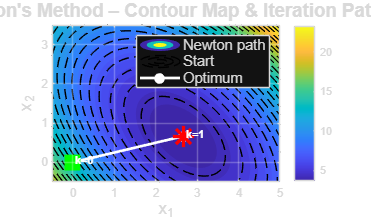


%% ── 5. Visualisation ─────────────────────────────────────────────────────

% ── 5a. Contour plot + Newton path ───────────────────────────────────────
figure('Name','Newton Method – Contour & Path','NumberTitle','off','Color','w');

[X1, X2] = meshgrid(linspace(-0.5, 5, 400), linspace(-0.5, 3.5, 400));
F_surf = (X1 - 3).^2 + (X2 - 2).^2 + X1.*X2;

contourf(X1, X2, F_surf, 40, 'LineColor','none');
colormap(parula); colorbar;
hold on;
contour(X1, X2, F_surf, 25, 'k', 'LineWidth', 0.4, 'LineStyle','--');

% Descent path
plot(hist_x(:,1), hist_x(:,2), 'w-o', ...
     'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor','w');
plot(x0(1), x0(2), 'gs', 'MarkerSize', 13, 'LineWidth', 2.5, ...
     'MarkerFaceColor','g', 'DisplayName','Start');
plot(x(1),  x(2),  'r*', 'MarkerSize', 16, 'LineWidth', 2.5, ...
     'DisplayName','Optimum');

% Annotate iterations
for i = 1:n_iter
    text(hist_x(i,1)+0.06, hist_x(i,2)+0.06, sprintf('k=%d',i-1), ...
         'Color','w', 'FontSize', 8, 'FontWeight','bold');
end

xlabel('x_1', 'FontSize', 13);
ylabel('x_2', 'FontSize', 13);
title('Newton''s Method – Contour Map & Iteration Path', ...
      'FontSize', 14, 'FontWeight', 'bold');
legend({'Newton path','Start','Optimum'}, 'Location','northeast','FontSize',11);
grid on; hold off;

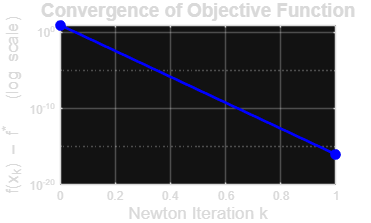


% ── 5b. Convergence: f(x) – f* (log scale) ───────────────────────────────
fstar = f(x);
figure('Name','Convergence – Objective','NumberTitle','off','Color','w');
semilogy(0:n_iter-1, abs(hist_f(1:n_iter) - fstar) + 1e-16, ...
         'b-o', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor','b');
xlabel('Newton Iteration k', 'FontSize', 13);
ylabel('f(x_k) – f^*   (log scale)', 'FontSize', 13);
title('Convergence of Objective Function', 'FontSize', 14, 'FontWeight','bold');
grid on; box on;

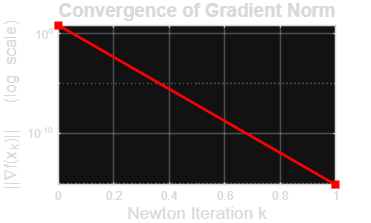


% ── 5c. Convergence: gradient norm (log scale) ───────────────────────────
figure('Name','Convergence – Gradient Norm','NumberTitle','off','Color','w');
semilogy(0:n_iter-1, hist_gnorm(1:n_iter) + 1e-16, ...
         'r-s', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor','r');
xlabel('Newton Iteration k', 'FontSize', 13);
ylabel('||\nablaf(x_k)||   (log scale)', 'FontSize', 13);
title('Convergence of Gradient Norm', 'FontSize', 14, 'FontWeight','bold');
grid on; box on;

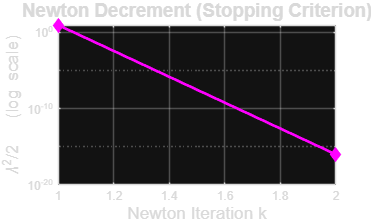


% ── 5d. Newton decrement λ²/2 (log scale) ────────────────────────────────
figure('Name','Newton Decrement','NumberTitle','off','Color','w');
semilogy(1:length(hist_lambda), hist_lambda + 1e-16, ...
         'm-d', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor','m');
xlabel('Newton Iteration k', 'FontSize', 13);
ylabel('\lambda^2/2   (log scale)', 'FontSize', 13);
title('Newton Decrement (Stopping Criterion)', 'FontSize', 14, 'FontWeight','bold');
grid on; box on;

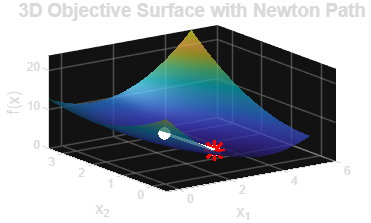


% ── 5e. 3-D surface + path ────────────────────────────────────────────────
figure('Name','3D Surface','NumberTitle','off','Color','w');
surf(X1, X2, F_surf, 'EdgeColor','none', 'FaceAlpha', 0.75);
colormap(parula); hold on;

% Project path onto surface
path_f = arrayfun(@(i) f(hist_x(i,:)'), 1:n_iter);
plot3(hist_x(:,1), hist_x(:,2), path_f', ...
      'w-o', 'LineWidth', 2.5, 'MarkerSize', 7, 'MarkerFaceColor','w');
plot3(x(1), x(2), f(x), 'r*', 'MarkerSize', 16, 'LineWidth', 2.5);

xlabel('x_1','FontSize',12); ylabel('x_2','FontSize',12); zlabel('f(x)','FontSize',12);
title('3D Objective Surface with Newton Path','FontSize',14,'FontWeight','bold');
view([-35, 30]); lighting phong; camlight('headlight');
grid on; hold off;

fprintf('  Plots generated: Contour path | f convergence | grad norm | Newton decrement | 3D surface\n\n');